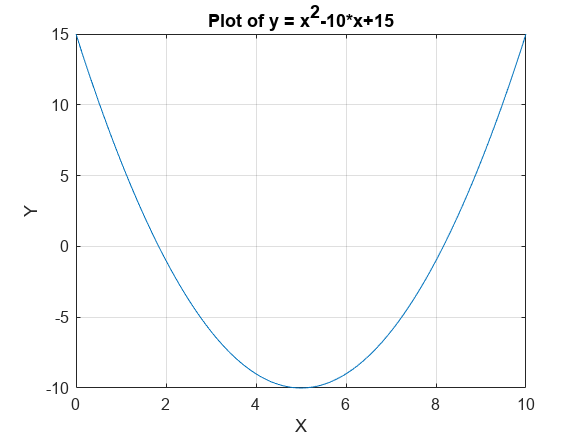

x = 0:0.1:10;
y = x.^2-10.*x+15;

plot(x,y)

title('Plot of y = x^2-10*x+15')
xlabel('X')
ylabel('Y')

grid on

%doc print

print('fig2', '-dpng')

Multiple plot

x = 0:pi/100:2*pi;
y1 = sin(2*x);
y2 = 2*cos(2*x);
y3 = cos(3*x)

y3 =     1.0000    0.9956    0.9823    0.9603    0.9298    0.8910    0.8443    0.7902    0.7290    0.6613    0.5878    0.5090    0.4258    0.3387    0.2487    0.1564    0.0628   -0.0314   -0.1253   -0.2181   -0.3090   -0.3971   -0.4818   -0.5621   -0.6374   -0.7071   -0.7705   -0.8271   -0.8763   -0.9178   -0.9511   -0.9759   -0.9921   -0.9995   -0.9980   -0.9877   -0.9686   -0.9409   -0.9048   -0.8607   -0.8090   -0.7501   -0.6845   -0.6129   -0.5358   -0.4540   -0.3681   -0.2790   -0.1874   -0.0941


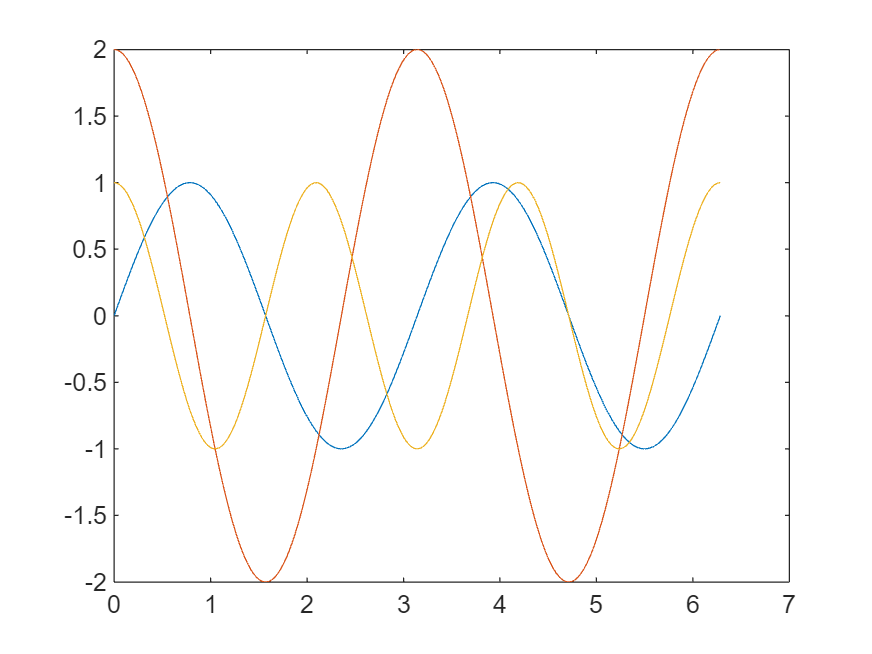


plot(x,y1)
hold on
plot(x,y2)
plot(x,y3)
hold off


plot(x,y1,x,y2,x,y3)

Line Color and ....

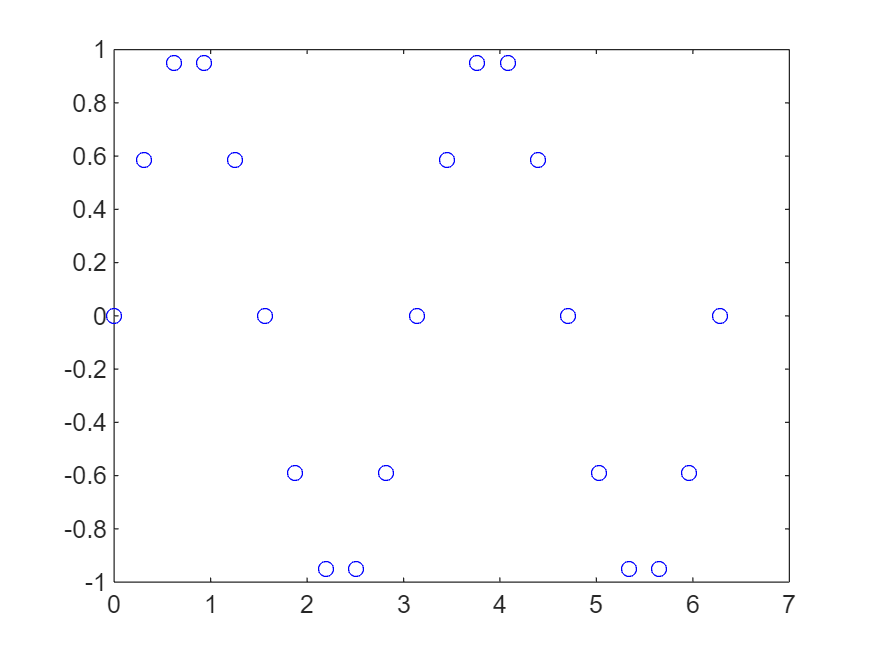

x = 0:pi/10:2*pi;
y1 = sin(2*x);
y2 = 2*cos(2*x);

plot(x,y1,'bo')

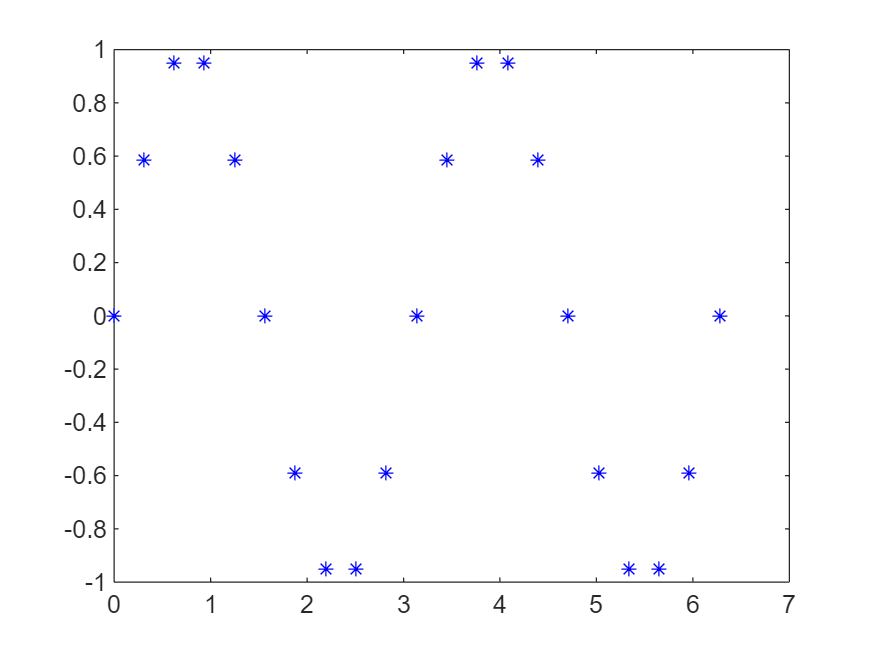


plot(x,y1,'b*')

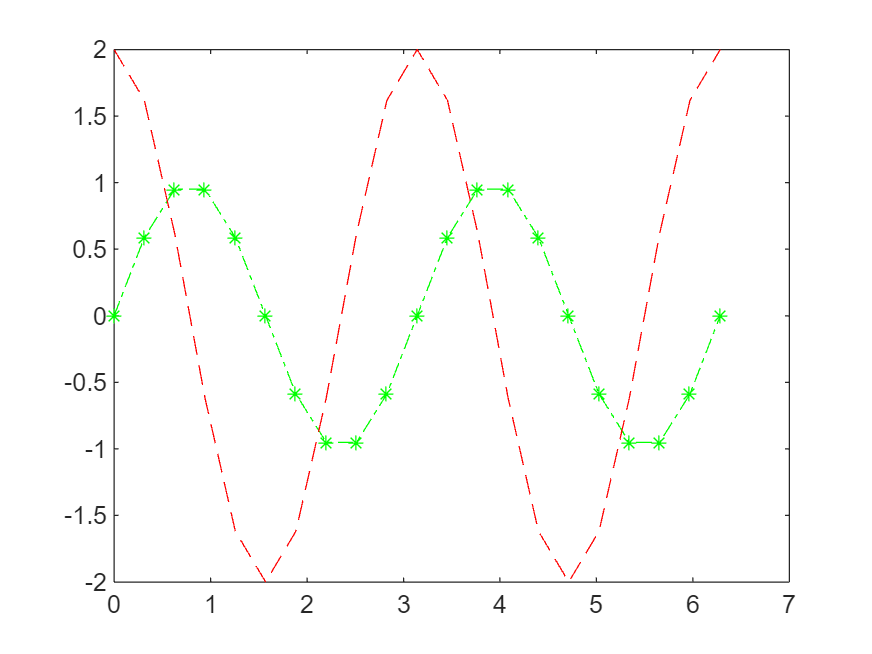


plot(x,y1,'g-.*',x,y2,'r--')

Legend

x = 0:pi/10:2*pi;
y1 = sin(2*x);
y2 = 2*cos(2*x);

plot(x,y1,'bo')


plot(x,y1,'b*')


plot(x,y1,'g-.*',x,y2,'r--')
legend('f(x)', 'd/dx f(x)','Location','northeastoutside')
legend off

Logarithmic Scales

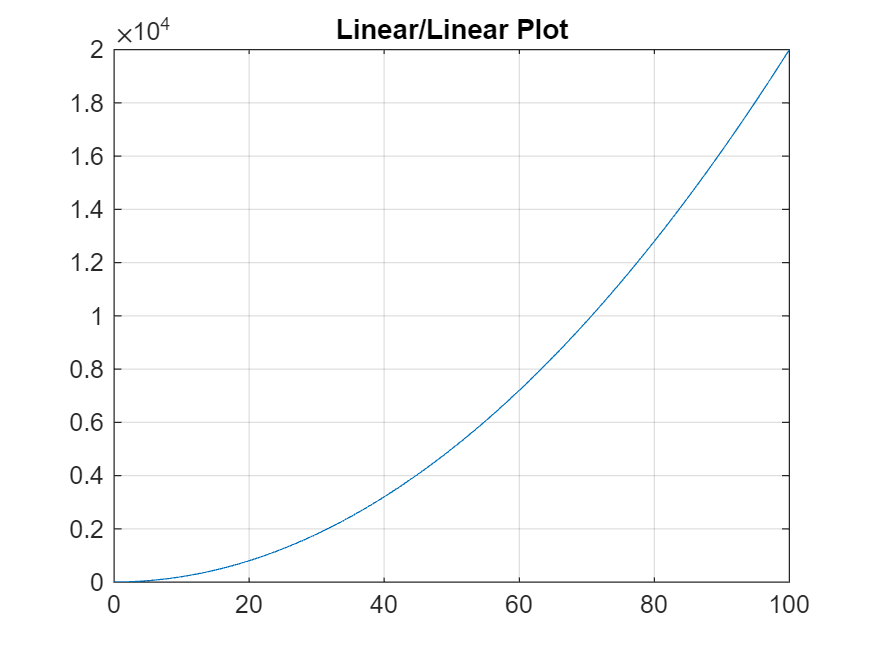


x = 0:0.2:100;
y = 2*x.^2;

plot(x,y)
title('Linear/Linear Plot')
grid on

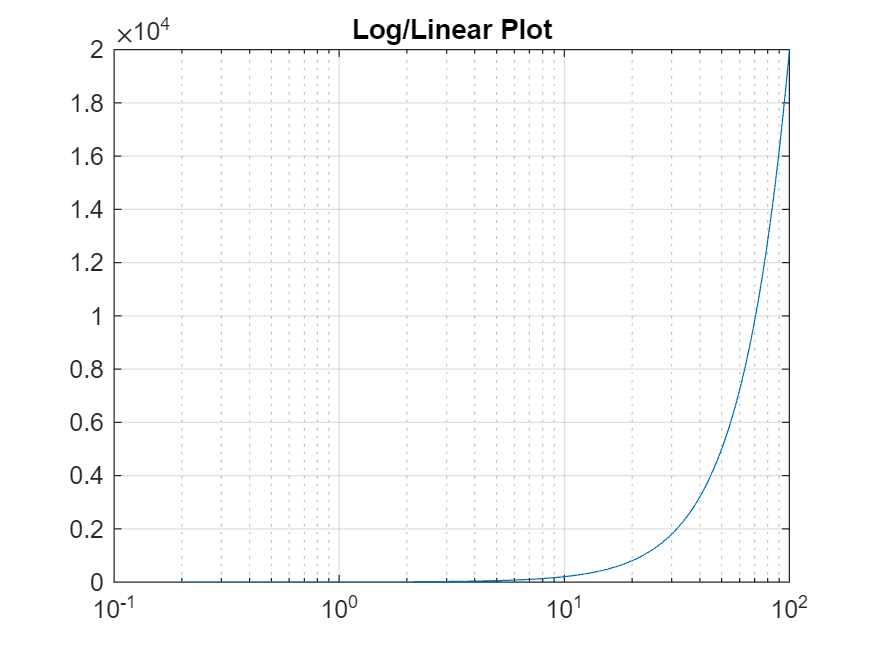



semilogx(x,y)
title('Log/Linear Plot')
grid on

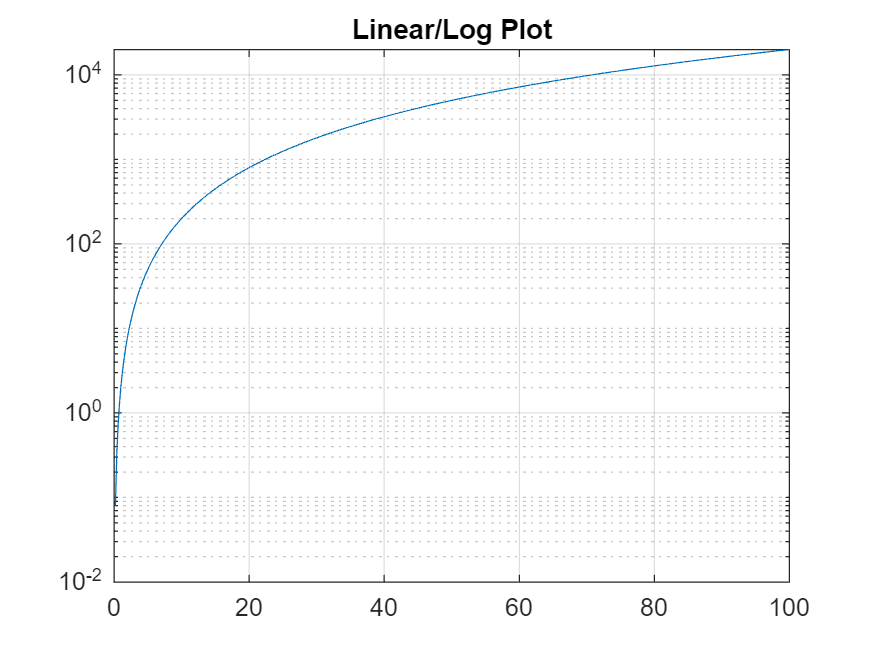


semilogy(x,y)
title('Linear/Log Plot')
grid on

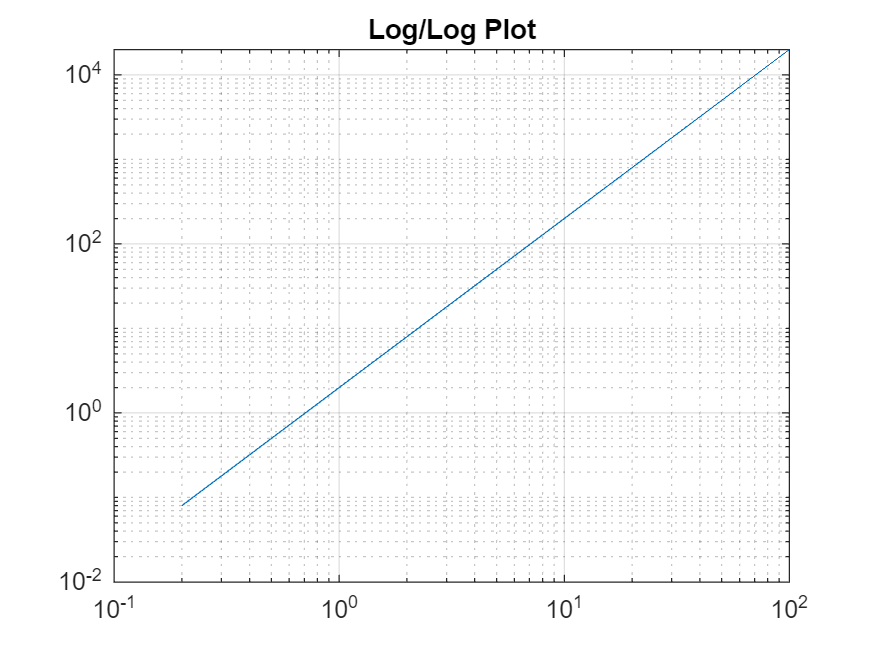


loglog(x,y)
title('Log/Log Plot')
grid on

Controlling x- and y-axis Plotting Limits

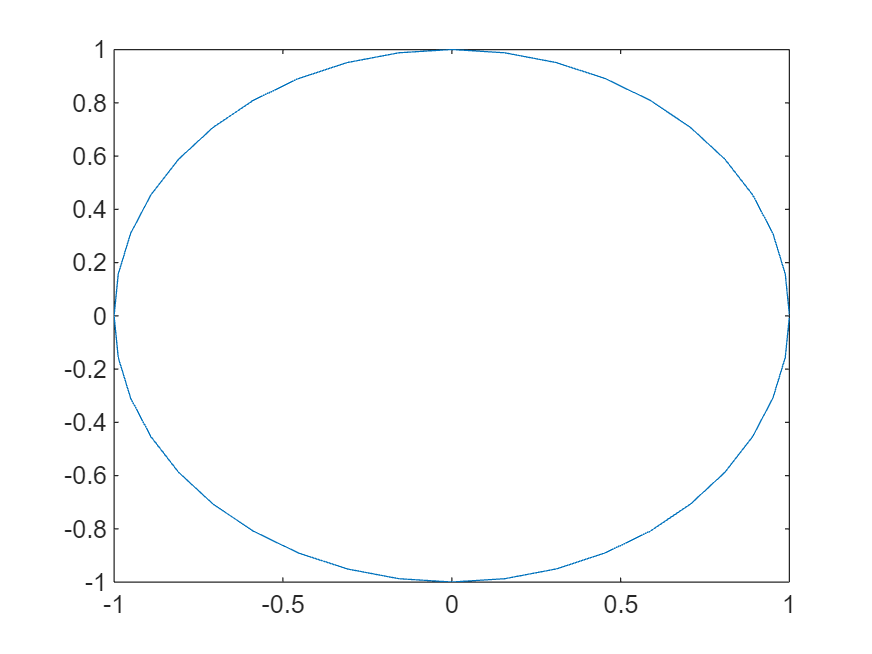


x = -2*pi:pi/20:2*pi;
y = sin(x);
z = cos(x);

plot(y,z)
axis([0 2 -1 1])
axis auto
axis equal
axis square
axis normal
axis tight
axis off
axis on

Subplot

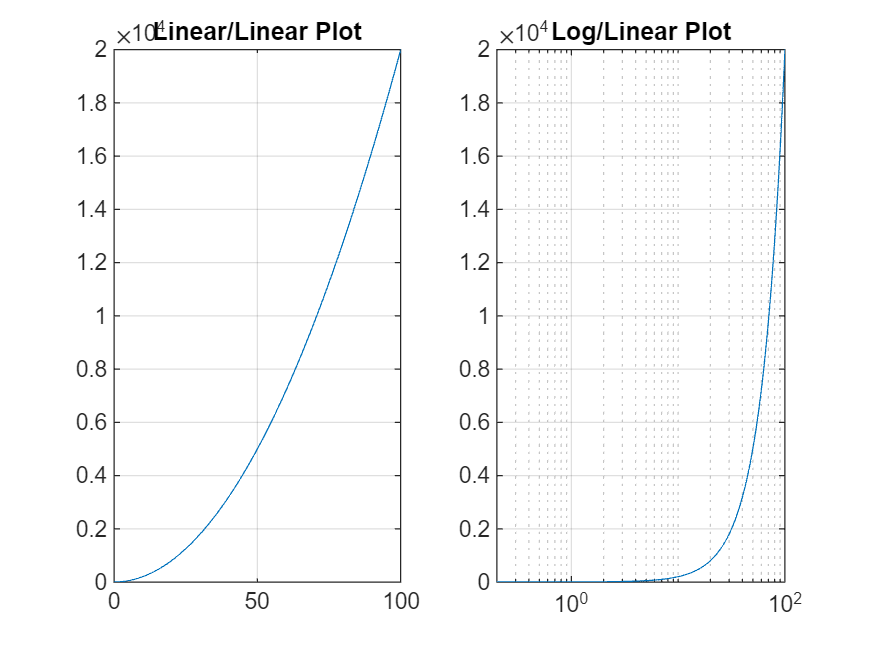

x = 0:0.2:100;
y = 2*x.^2;

subplot(1,2,1)
plot(x,y)
title('Linear/Linear Plot')
grid on

subplot(1,2,2)
semilogx(x,y)
title('Log/Linear Plot')
grid on

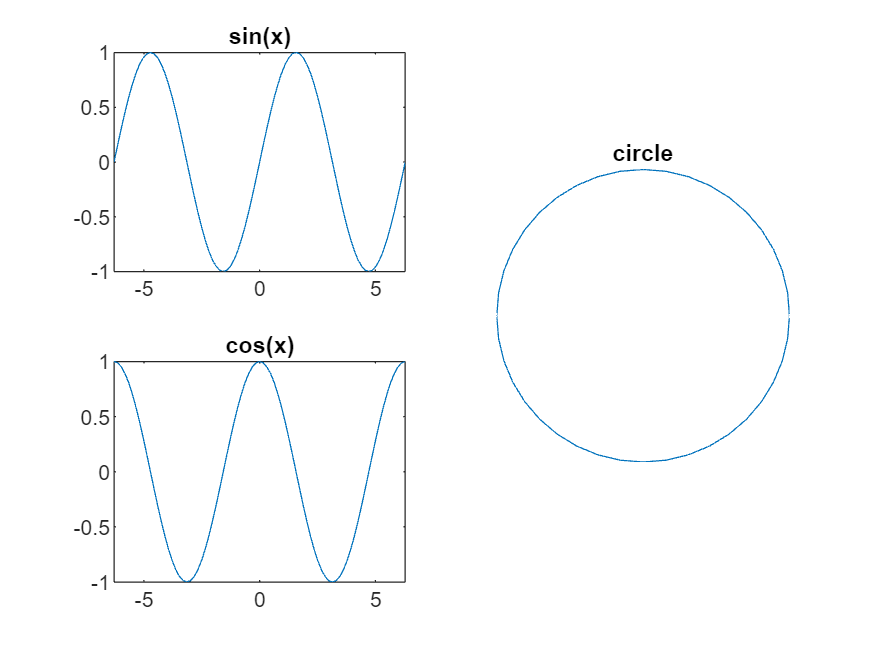

x = -2*pi:pi/20:2*pi;
y = sin(x);
z = cos(x);

subplot(2,2,1);
plot(x,y);
title('sin(x)')

subplot(2,2,3);
plot(x,z);
title('cos(x)')


subplot(2,2,[2 4]);

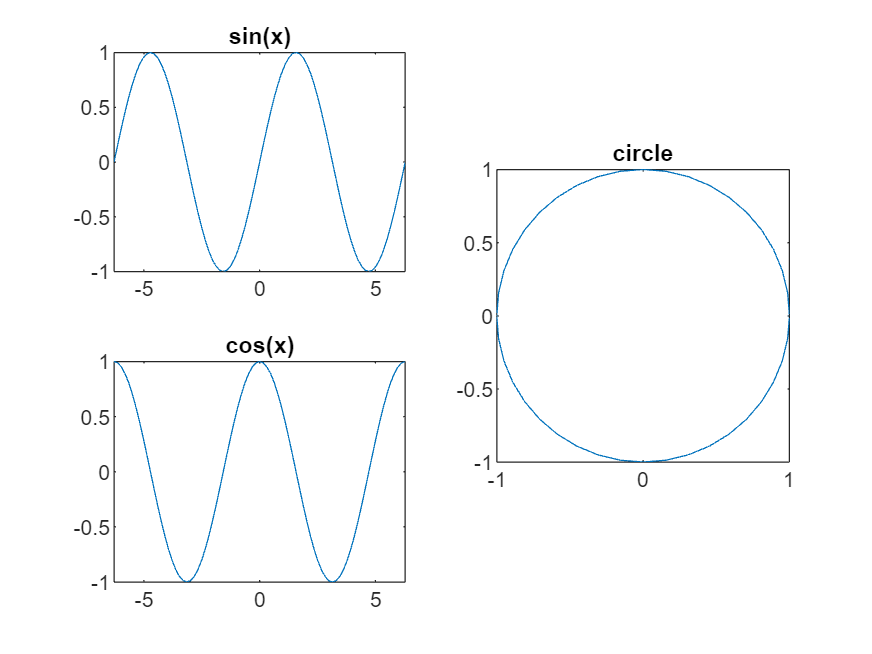

plot(y,z);
title('circle')
axis equal
axis square

Enhanced Control of Plotted Lines

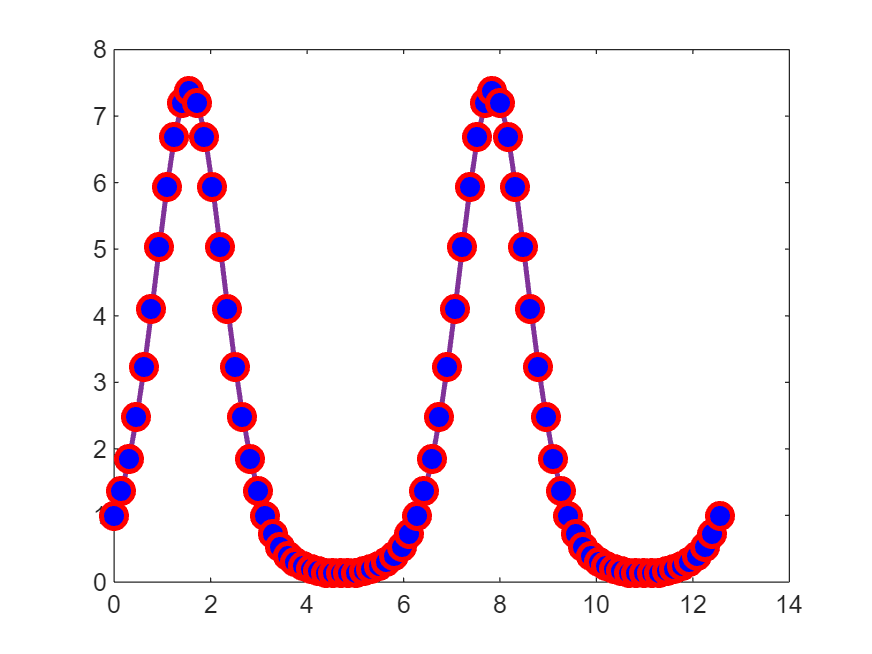

%doc plot

x = 0:pi/20:4*pi;
y = exp(2*sin(x));

figure
plot(x,y,'-o','Color',[0.5 0.2 0.6], 'LineWidth', 2.0, 'MarkerSize', 10, ...
    'MarkerEdgeColor','r','MarkerFaceColor','b')

Enhanced Control of Text String

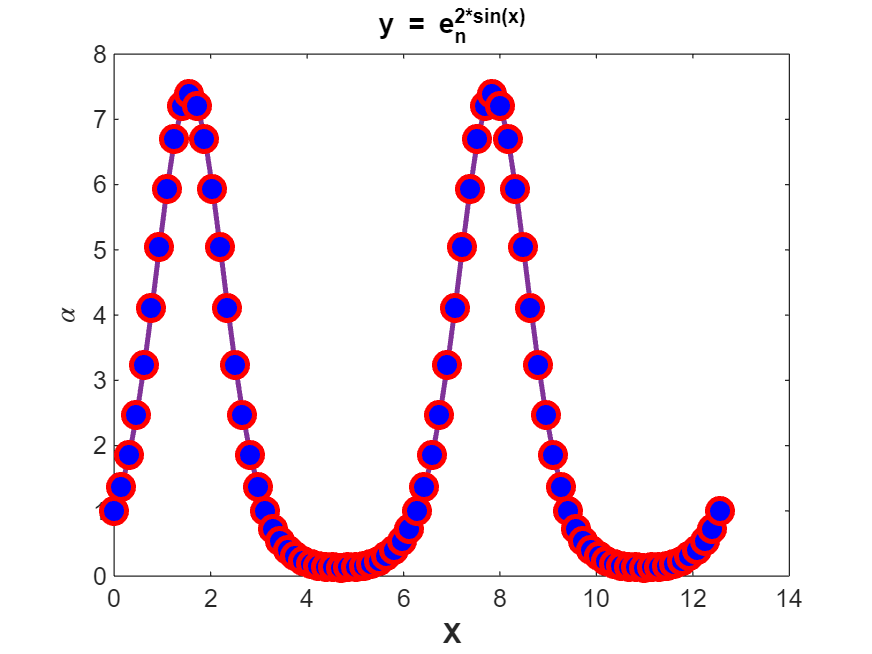

x = 0:pi/20:4*pi;
y = exp(2*sin(x));

plot(x,y,'-o','Color',[0.5 0.2 0.6], 'LineWidth', 2.0, 'MarkerSize', 10, ...
    'MarkerEdgeColor','r','MarkerFaceColor','b')
title('\ity = e_{n}^{2*sin(x)}')
xlabel('\bfX')
ylabel('\alpha')

y as a Matrix

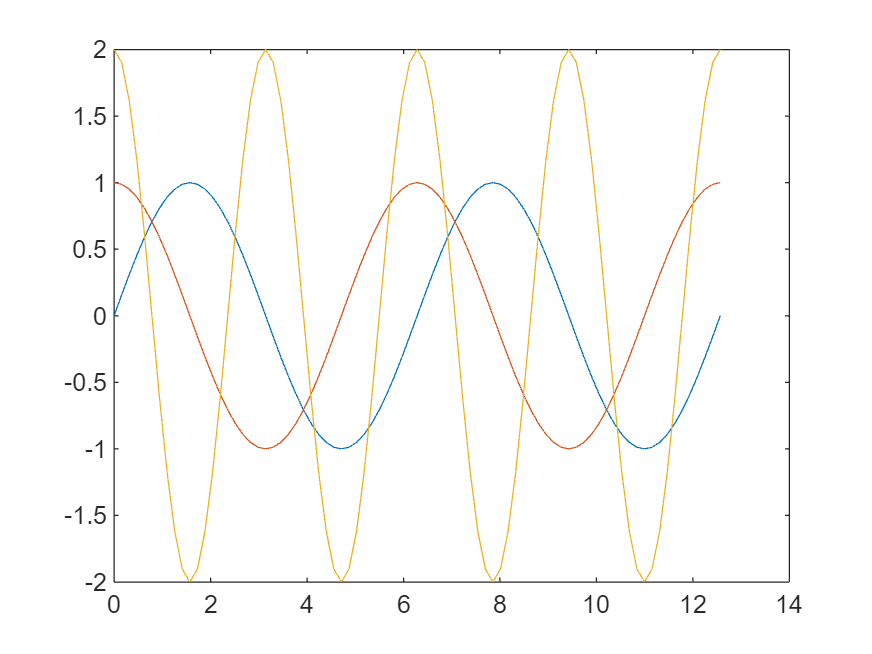

clear

x = 0:pi/20:4*pi;
y(1,:) = sin(x);
y(2,:) = cos(x);
y(3,:) = 2*cos(2*x);
%y(4,:) = 2*sin(2*x)

plot(x,y)